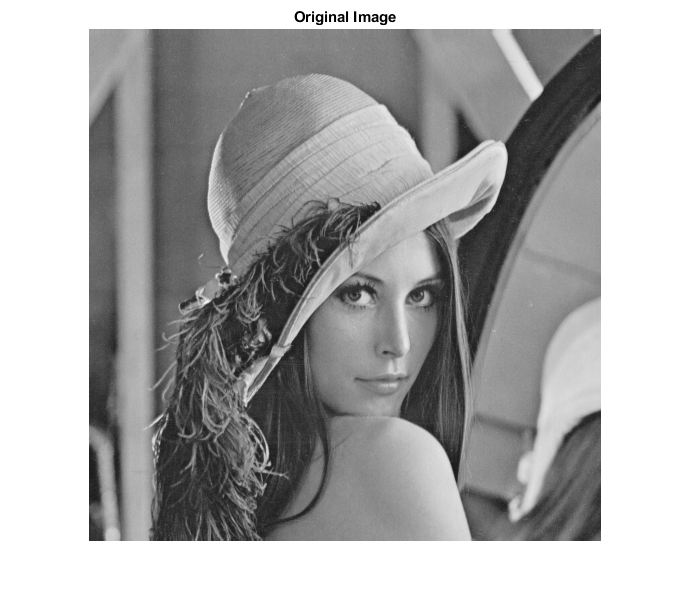

% Edge Detection
I = im2uint8(rgb2gray(imread("lena_std.tif")));
imshow(I), title("Original Image");

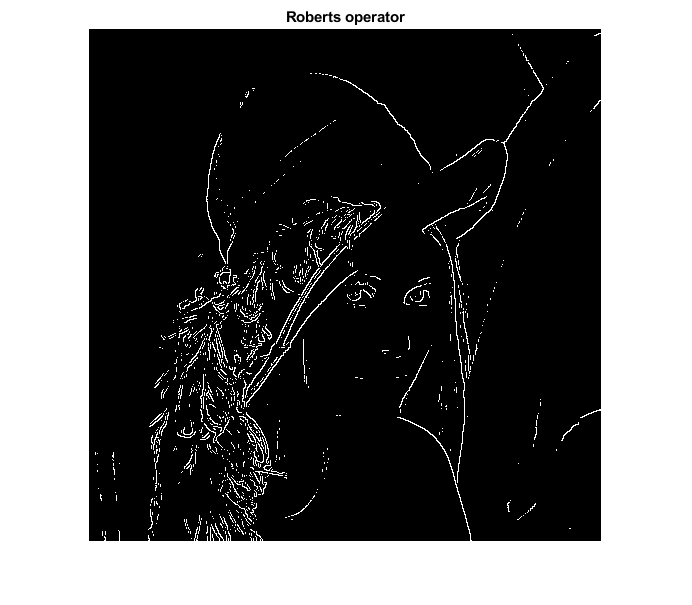


% Roberts operator
filter1 = edge(I,"Roberts");
imshow(filter1), title("Roberts operator");

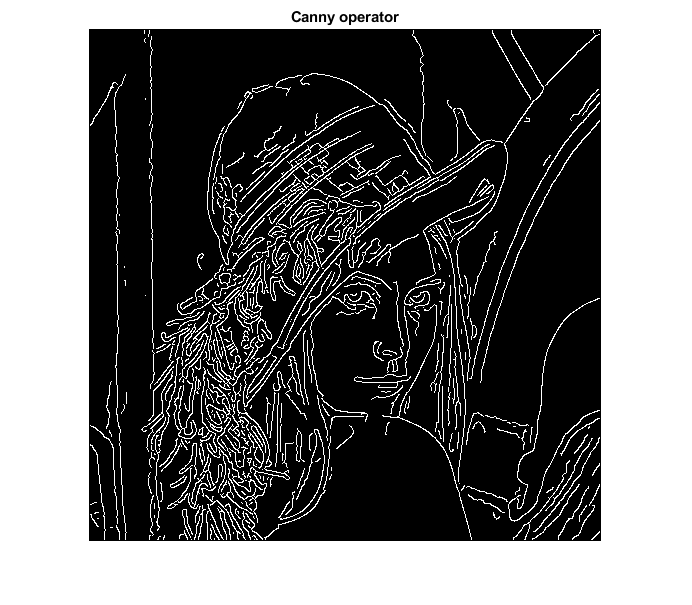


% Canny operator
filter2 = edge(I,"Canny");
imshow(filter2), title("Canny operator");

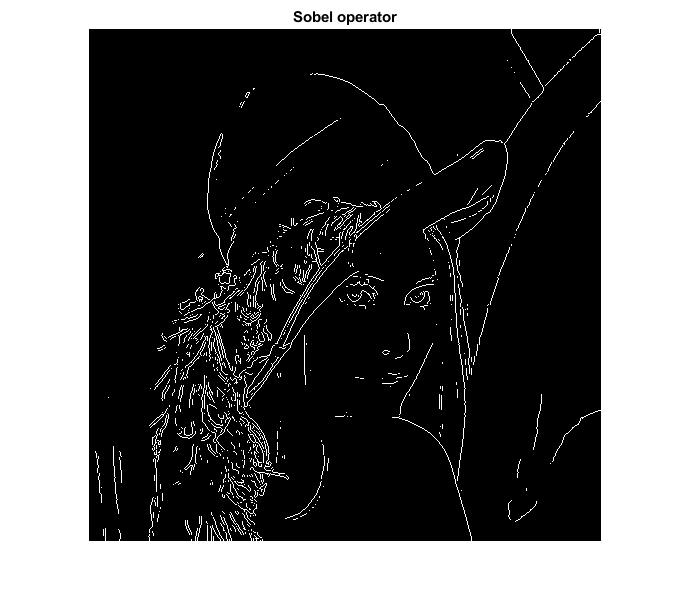


% Sobel operator
filter3 = edge(I,"Sobel");
imshow(filter3), title("Sobel operator");

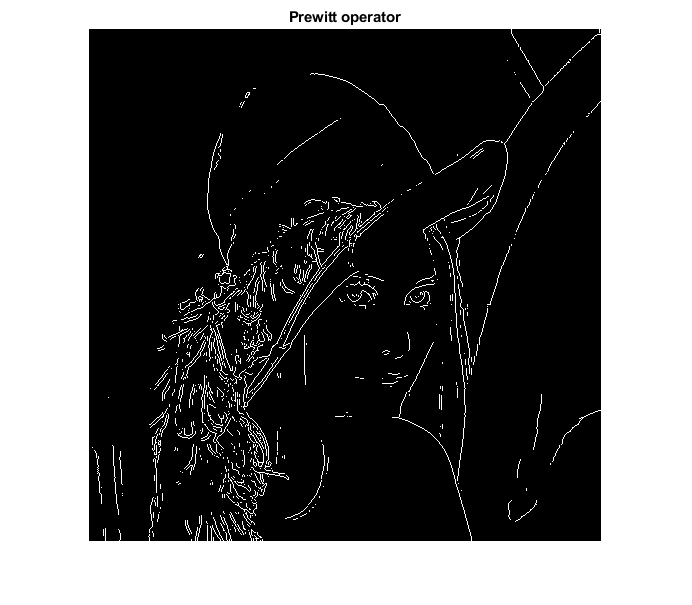


% Prewitt operator
filter4 = edge(I,"Prewitt");
imshow(filter4), title("Prewitt operator");

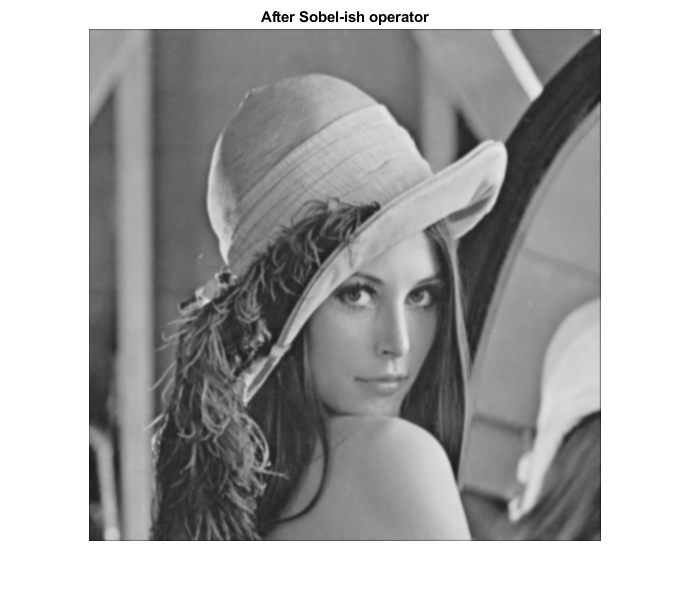


% Edge Filter
o = gaussianOperator(7,1);
fil_gau = imfilter(I,o);
imshow(fil_gau), title("After Sobel-ish operator");


% Histogram-based segmentation
% a
imshow(I), title("Original Image");

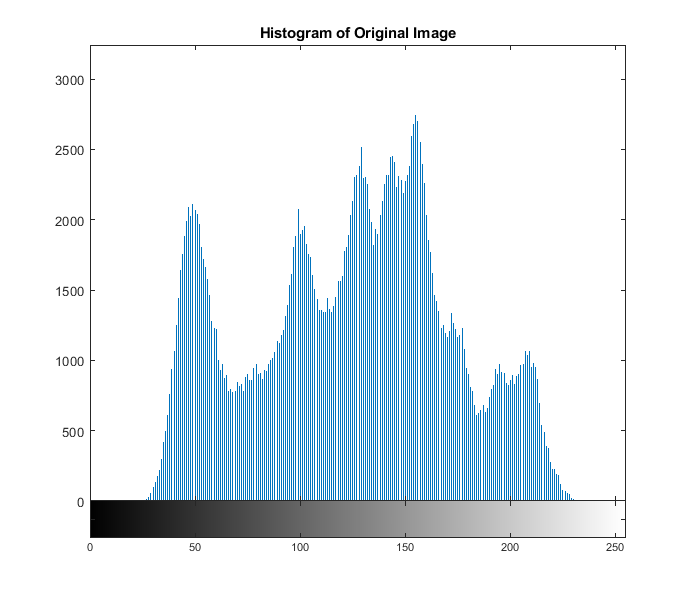


% b
imhist(I), title("Histogram of Original Image");

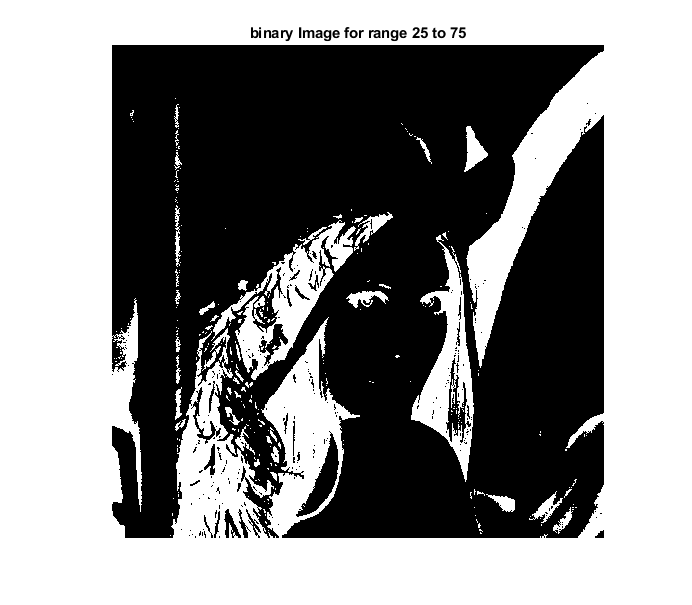


% c
R1 = [25,75];
R2 = [160,180];
R3 = [200,300];

% d
B1 = uint8(255*((I>=R1(1))&(I<=R1(2))));
imshow(B1), title("binary Image for range "+R1(1)+" to "+R1(2));

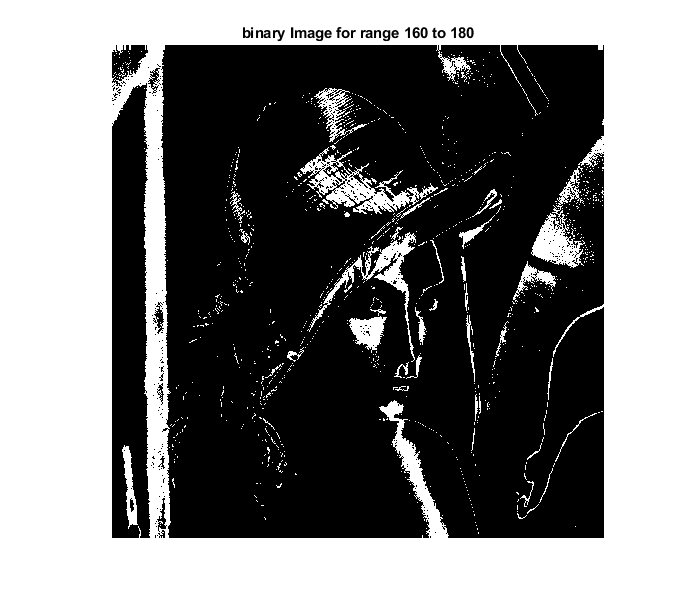

B2 = uint8(255*((I>=R2(1))&(I<=R2(2))));
imshow(B2), title("binary Image for range "+R2(1)+" to "+R2(2));

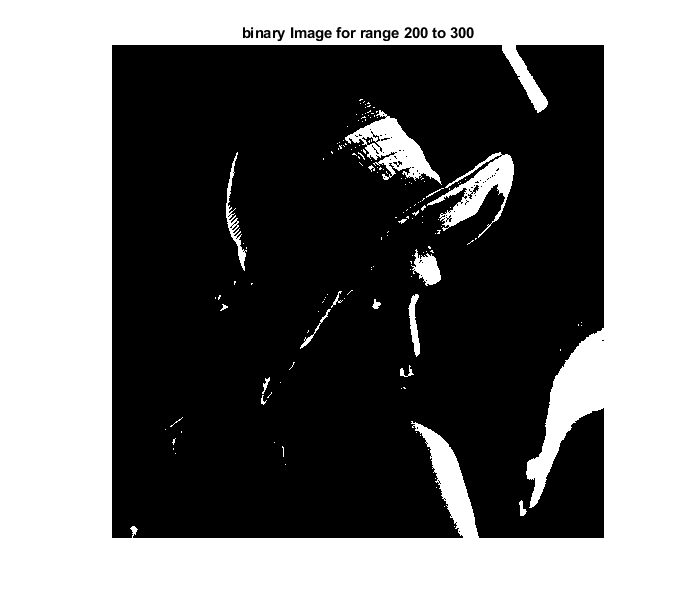

B3 = uint8(255*((I>=R3(1))&(I<=R3(2))));
imshow(B3), title("binary Image for range "+R3(1)+" to "+R3(2));

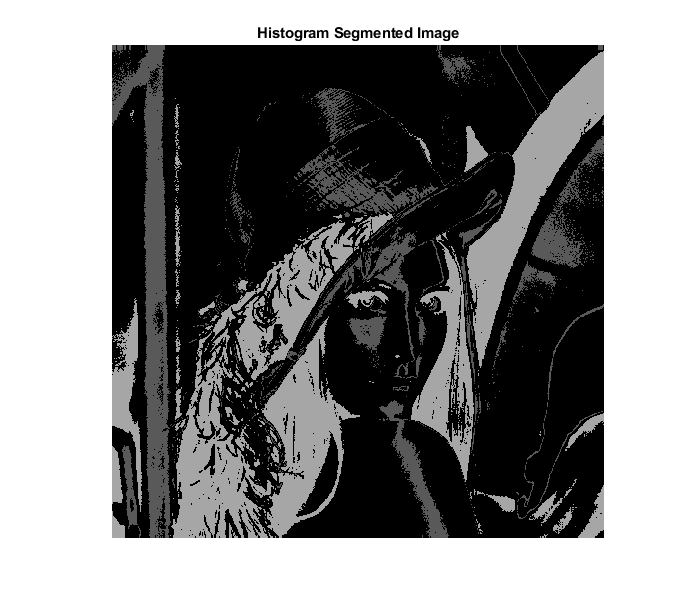


%e
base = sum(sum(B1))+sum(sum(B2));
m1 = sum(sum(B1.*I))/base;
m2 = sum(sum(B2.*I))/base;
c = m1*B1 + m2*B2;
imshow(c), title("Histogram Segmented Image");

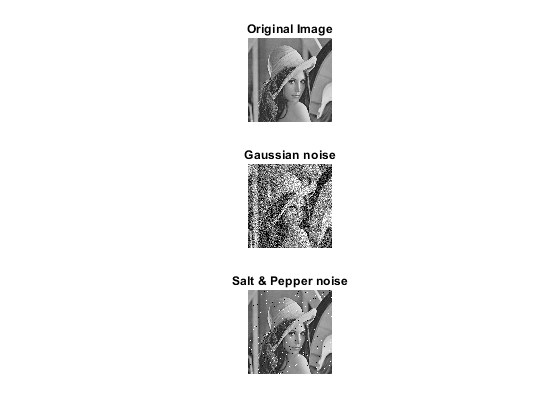


% Noise reduction
% a
noise_gaussian = imnoise(I,'gaussian',0,0.05);
noise_saltAndpepper = imnoise(I,'salt & pepper',0.02);

% b
figure;
subplot(3,1,1);
imshow(I), title("Original Image");
subplot(3,1,2);
imshow(noise_gaussian), title("Gaussian noise");
subplot(3,1,3);
imshow(noise_saltAndpepper), title("Salt & Pepper noise");

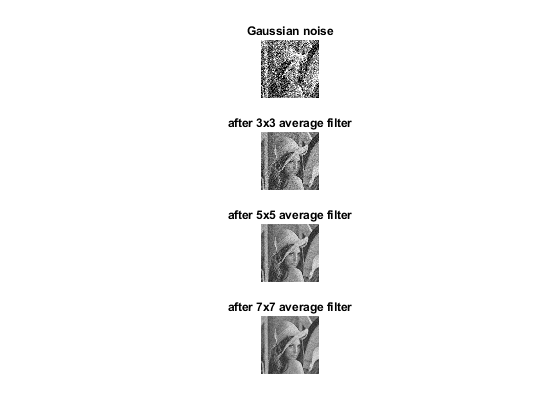


% c
h3 = fspecial('average',3);
h5 = fspecial('average',5);
h7 = fspecial('average',7);
fil_gau3 = imfilter(noise_gaussian,h3);
fil_gau5 = imfilter(noise_gaussian,h5);
fil_gau7 = imfilter(noise_gaussian,h7);

figure;
subplot(4,1,1);
imshow(noise_gaussian), title("Gaussian noise");
subplot(4,1,2);
imshow(fil_gau3), title("after 3x3 average filter");
subplot(4,1,3);
imshow(fil_gau5), title("after 5x5 average filter");
subplot(4,1,4);
imshow(fil_gau7), title("after 7x7 average filter");

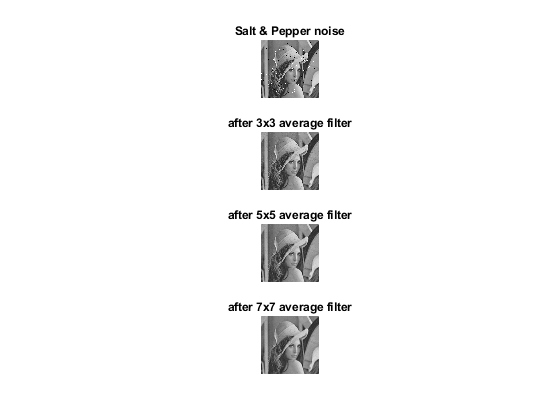


fil_slt3 = imfilter(noise_saltAndpepper,h3);
fil_slt5 = imfilter(noise_saltAndpepper,h5);
fil_slt7 = imfilter(noise_saltAndpepper,h7);

figure;
subplot(4,1,1);
imshow(noise_saltAndpepper), title("Salt & Pepper noise");
subplot(4,1,2);
imshow(fil_slt3), title("after 3x3 average filter");
subplot(4,1,3);
imshow(fil_slt5), title("after 5x5 average filter");
subplot(4,1,4);
imshow(fil_slt7), title("after 7x7 average filter");

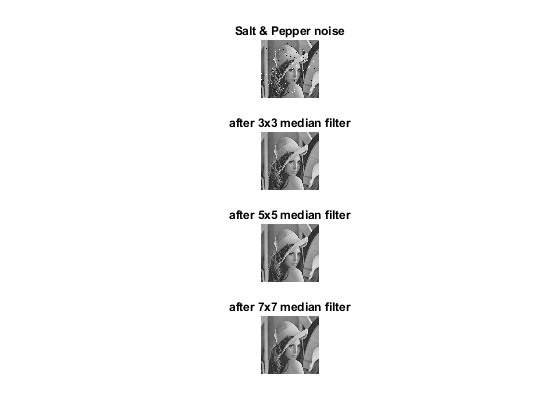


% d
m3 = medfilt2(noise_saltAndpepper,[3 3]);
m5 = medfilt2(noise_saltAndpepper,[5 5]);
m7 = medfilt2(noise_saltAndpepper,[7 7]);

figure;
subplot(4,1,1);
imshow(noise_saltAndpepper), title("Salt & Pepper noise");
subplot(4,1,2);
imshow(m3), title("after 3x3 median filter");
subplot(4,1,3);
imshow(m5), title("after 5x5 median filter");
subplot(4,1,4);
imshow(m7), title("after 7x7 median filter");

function o=gaussianOperator(size,sigma)
    o = zeros(size,size);
    for i=-(size-1)/2:(size-1)/2
        for j=-(size-1)/2:(size-1)/2
            x0=(size+1)/2;
            y0=(size+1)/2;
            x=i+x0;
            y=j+y0;
            o(y,x)=(x)/(-2*pi*((sigma)^4))*exp(-((x-x0)^2+(y-y0)^2)/2/sigma/sigma);
        end
    end
    sum1=sum(o);
    sum2=sum(sum1);
    o=o/sum2;
end